load Neural_Networks\5-signs\resnet_18\5-signs\Augmented\Network.mat
signds = imageDatastore("D:\college\FYP\test_images\output","IncludeSubfolders",true,"LabelSource","foldernames");
signNames = signds.Labels;

% Augmentation

resizeImgs = augmentedImageDatastore([224 224],signds);


% Prediction
signPrediction = classify(Network,resizeImgs);
signActual = signds.Labels;

% Create a folder to store wrongly predicted images
wrongPredictionFolder = "D:\college\FYP\test_images\wrong_predictions";

if ~exist(wrongPredictionFolder, 'dir')
    mkdir(wrongPredictionFolder);
end

% Compare predictions and save wrongly predicted images
for i = 1:numel(signPrediction)
    if ~strcmp(char(signPrediction(i)), char(signActual(i)))
        % Image was wrongly predicted
        imgPath = signTest.Files{i};
        [~, imgName, imgExt] = fileparts(imgPath);
        imgLabel = char(signActual(i));
        outputFolder = fullfile(wrongPredictionFolder, imgLabel);
        
        % Create the class label folder if it doesn't exist
        if ~exist(outputFolder, 'dir')
            mkdir(outputFolder);
        end
        
        % Copy the image to the respective folder
        outputImgPath = fullfile(outputFolder, strcat(imgName, imgExt));
        copyfile(imgPath, outputImgPath);
    end
end

% Comparison
numCorrect = nnz(signPrediction == signActual);
fracCorrect = numCorrect / numel(signPrediction);

% Display accuracy
fprintf("Accuracy: %.2f%%\n", fracCorrect * 100);

Accuracy: 96.66%


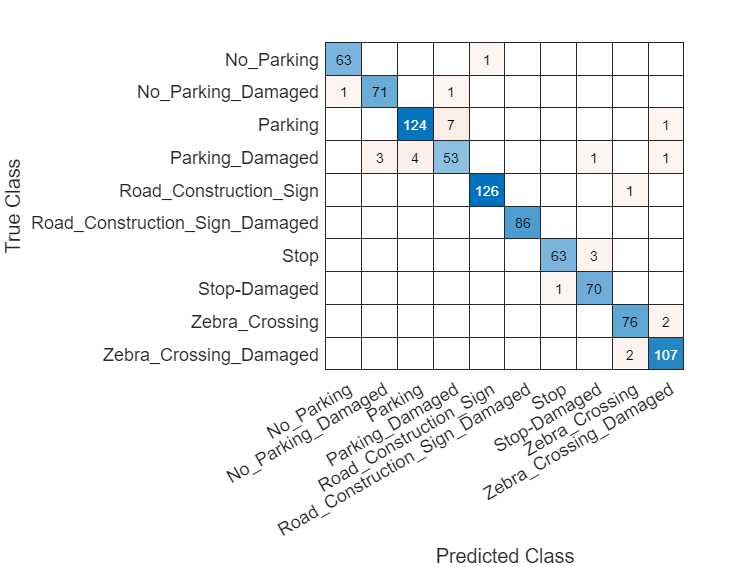


% Confusion Chart
confusionchart(signActual, signPrediction);